# FIR and IIR Filtering

## Question 1

Write a MATLAB Program to compute and display the poles and zeros, to compute and display the factor form, and to generate the pol-zero plot of the z-transform that is a ratio of two polynomials in z-1. Using this program, analyze the z-transform G(z) of Equation 1.

Zeros:
  -1.0000 - 1.4142i  -1.0000 + 1.4142i  -0.2500 - 0.6614i  -0.2500 + 0.6614i

Poles:
  -8.9576 + 0.0000i  -0.2718 + 0.0000i   0.1147 - 0.2627i   0.1147 + 0.2627i

Factored G(z)
                                                / sqrt(7) 1i   1     \ / sqrt(7) 1i   1     \
                                                | ---------- - -     | | ---------- + -     |
/ - 1 + sqrt(2) 1i     \ / 1 + sqrt(2) 1i     \ |      4       4     | |      4       4     |
| ---------------- - 1 | | -------------- + 1 | | -------------- - 1 | | -------------- + 1 |
\         z            / \        z           / \        z           / \        z           /



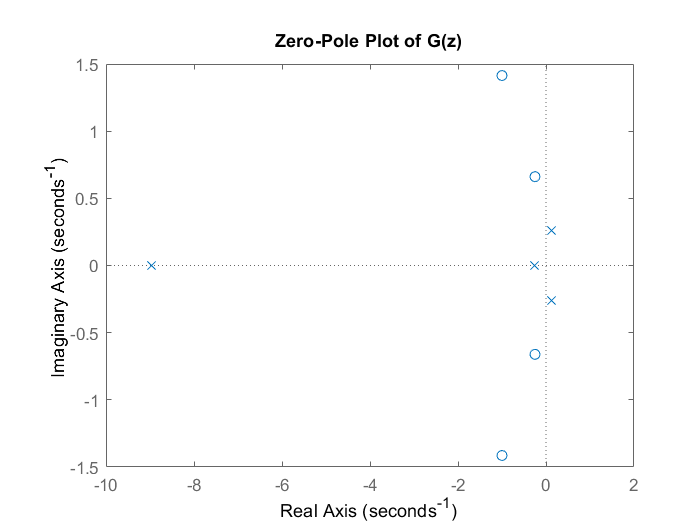

num = [2,5,9,5,3];
den = [5,45,2,1,1];
[p_i1,z_i1] = question1(num,den,"G(z)");

## Question 2

Write a MATLAB program to compute and display the rational z-transform from its zeros, poles, and gain constant. Using this program, determine the rational form of a z-transform with the given zeros, poles, and gain constant.

z_i = [0.3,2.5,-0.2+1j*0.4,-0.2-1j*0.4];
p_i = [0.5,-0.75,0.6+1j*0.7,0.6-1j*0.7];
b0 = 3.9;
[b,a] = question2(z_i,p_i,b0)

G(z) = 
        4        3        2
    39 z    234 z    663 z    507 z   117
  - ----- + ------ + ------ + ----- - ---
      10      25      1000     500    200
- ---------------------------------------
                3      2
        4   19 z    7 z    53 z    51
       z  - ----- + ---- + ---- - ---
              20     40     80    160



b =     3.9000   -9.3600   -0.6630   -1.0140    0.5850


a =     1.0000   -0.9500    0.1750    0.6625   -0.3187


## Question 3

Write a MATLAB program to compute and display the magnitude and phase response of a filter with rational z-transform. Use this program to display the magnitude and phase response for G(z).

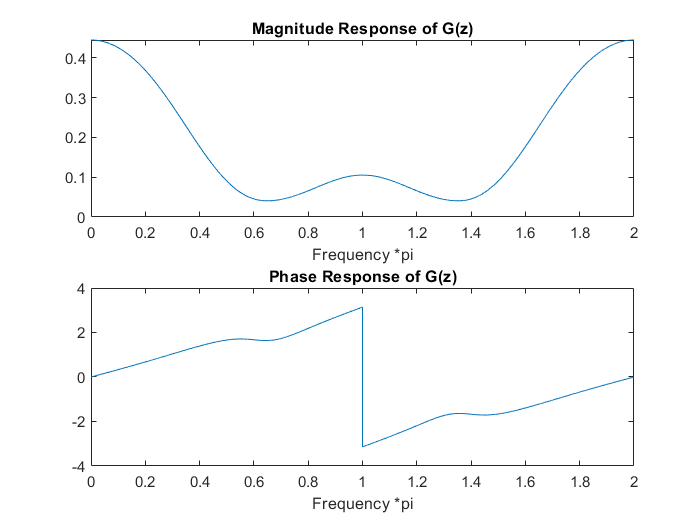

num = [2,5,9,5,3];
den = [5,45,2,1,1];
question3(num,den,"G(z)");

## Question 4

The audio signal in http://tinyurl.com/ja5vxce has been contaminated with multiple additive noisy signals with narrow spectral content. The goal of this project is to clean the audio by designing different notch filters.

- Plot the magnitude and phase response of the audio file.

- Determine the spectral location associated with the noise. Give your results in the discrete time domain (normalizes frequencies) and continuous time domain (in Hz).

- Design a notch FIR filter with only zeros. Plot the magnitude and phase response of the filter. Plot the magnitude response of the resulting signal. Create an audio file after filtering the signal.

- Design a notch IIR filter with zeros and poles. Set the magnitude of the poles to r = 0.4 (pk = r*e^(jw_k) ). Plot the magnitude and phase response of the filter. Plot the magnitude response of the resulting signal. Create an audio file after filtering the signal.

- Repeat part (d) with r = 0.95

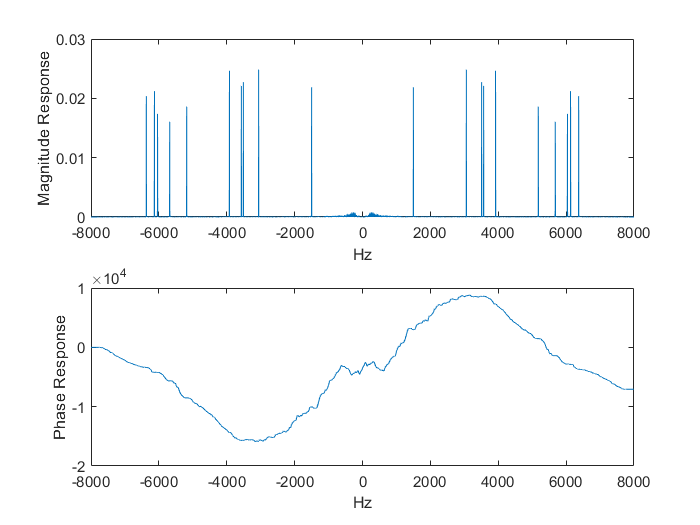

Frequencies of Noise (Hz):
   1.0e+03 *

    1.5000    3.0600    3.5100    3.5699    3.9200    5.1800    5.6799    6.0400    6.1299    6.3699

Discrete Normalized Frequencies of Noise:
    0.0937    0.1912    0.2194    0.2231    0.2450    0.3237    0.3550    0.3775    0.3831    0.3981



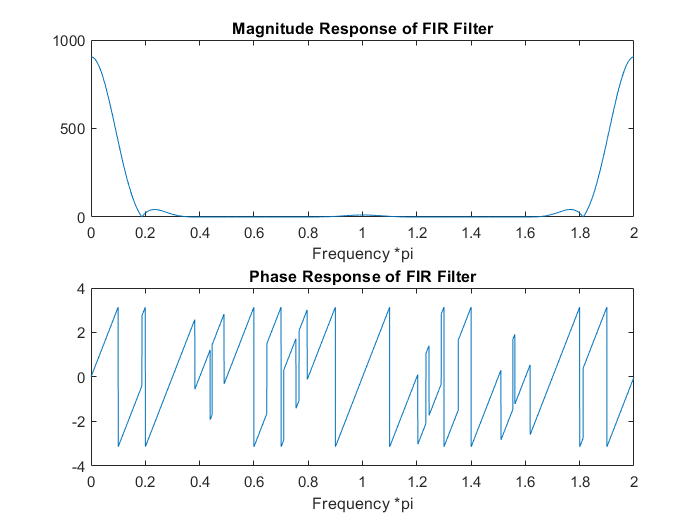

Zeros:
  Columns 1 through 14

   0.8315 - 0.5556i   0.8315 + 0.5556i   0.3608 - 0.9326i   0.3608 + 0.9326i   0.1912 - 0.9815i   0.1912 + 0.9815i   0.1681 - 0.9858i   0.1681 + 0.9858i   0.0314 - 0.9995i   0.0314 + 0.9995i  -0.4470 - 0.8945i  -0.4470 + 0.8945i  -0.8020 - 0.5973i  -0.8020 + 0.5973i

  Columns 15 through 20

  -0.7423 - 0.6701i  -0.7423 + 0.6701i  -0.7181 - 0.6959i  -0.7181 + 0.6959i  -0.6129 - 0.7902i  -0.6129 + 0.7902i

Poles:
Factored G(z)
/  566085731962705    9002750976819333      \ /  566085731962705    9002750976819333      \ / 5520343083264219   3558632133896769      \ / 5520343083264219   3558632133896769      \ / 1513968334038139   4439525264545937      \ / 1513968334038139   4439525264545937      \
| ----------------- - ----------------i     | | ----------------- + ----------------i     | | ---------------- - ----------------i     | | ---------------- + ----------------i     | | ---------------- - ----------------i     | | ---------------- + ----------------i  

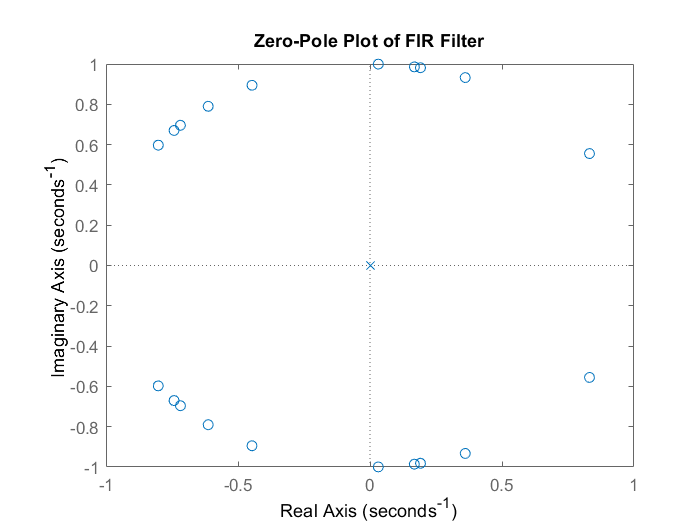

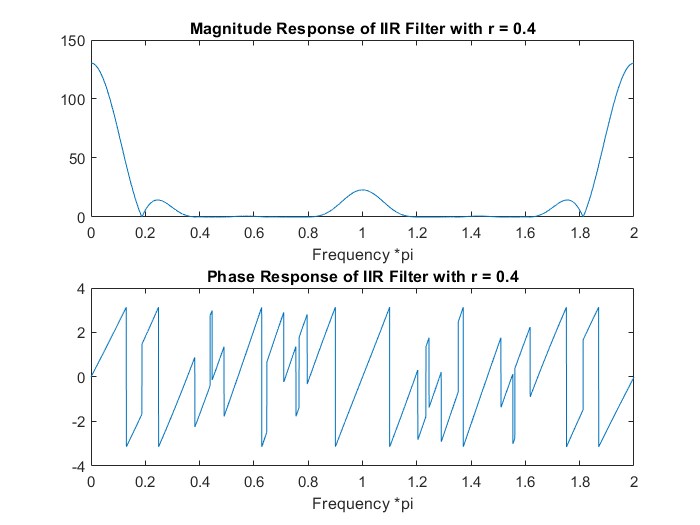

Zeros:
  Columns 1 through 14

   0.8315 - 0.5556i   0.8315 + 0.5556i   0.3608 - 0.9326i   0.3608 + 0.9326i   0.1912 - 0.9815i   0.1912 + 0.9815i   0.1681 - 0.9858i   0.1681 + 0.9858i   0.0314 - 0.9995i   0.0314 + 0.9995i  -0.4470 - 0.8945i  -0.4470 + 0.8945i  -0.8020 - 0.5973i  -0.8020 + 0.5973i

  Columns 15 through 20

  -0.7423 - 0.6701i  -0.7423 + 0.6701i  -0.7181 - 0.6959i  -0.7181 + 0.6959i  -0.6129 - 0.7902i  -0.6129 + 0.7902i

Poles:
  Columns 1 through 14

   0.3326 - 0.2222i   0.3326 + 0.2222i   0.1443 - 0.3731i   0.1443 + 0.3731i   0.0765 - 0.3926i   0.0765 + 0.3926i   0.0672 - 0.3943i   0.0672 + 0.3943i   0.0126 - 0.3998i   0.0126 + 0.3998i  -0.1788 - 0.3578i  -0.1788 + 0.3578i  -0.3208 - 0.2389i  -0.3208 + 0.2389i

  Columns 15 through 20

  -0.2969 - 0.2680i  -0.2969 + 0.2680i  -0.2873 - 0.2784i  -0.2873 + 0.2784i  -0.2452 - 0.3161i  -0.2452 + 0.3161i

Factored G(z)
/  566085731962705    9002750976819333      \ /  566085731962705    9002750976819333      \ / 552034308326

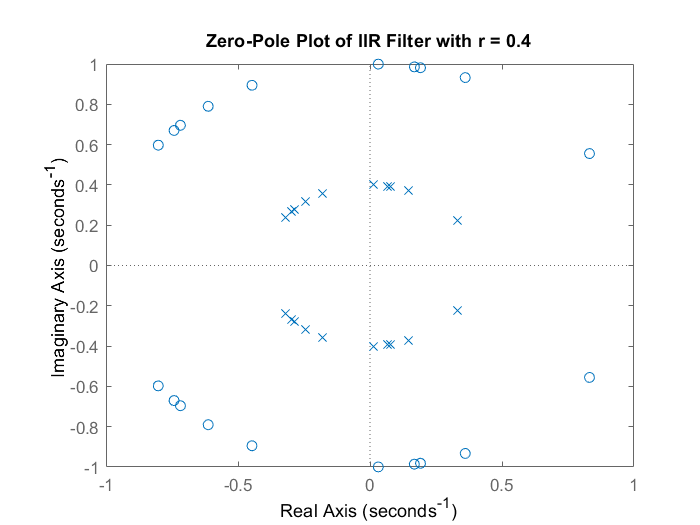

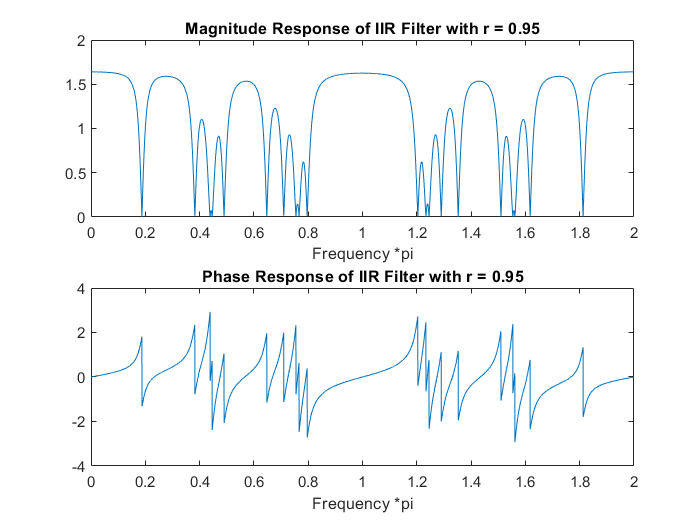

Zeros:
  Columns 1 through 14

   0.8315 - 0.5556i   0.8315 + 0.5556i   0.3608 - 0.9326i   0.3608 + 0.9326i   0.1912 - 0.9815i   0.1912 + 0.9815i   0.1681 - 0.9858i   0.1681 + 0.9858i   0.0314 - 0.9995i   0.0314 + 0.9995i  -0.4470 - 0.8945i  -0.4470 + 0.8945i  -0.8020 - 0.5973i  -0.8020 + 0.5973i

  Columns 15 through 20

  -0.7423 - 0.6701i  -0.7423 + 0.6701i  -0.7181 - 0.6959i  -0.7181 + 0.6959i  -0.6129 - 0.7902i  -0.6129 + 0.7902i

Poles:
  Columns 1 through 14

   0.7899 - 0.5278i   0.7899 + 0.5278i   0.3428 - 0.8860i   0.3428 + 0.8860i   0.1817 - 0.9325i   0.1817 + 0.9325i   0.1597 - 0.9365i   0.1597 + 0.9365i   0.0299 - 0.9495i   0.0299 + 0.9495i  -0.4246 - 0.8498i  -0.4246 + 0.8498i  -0.7619 - 0.5674i  -0.7619 + 0.5674i

  Columns 15 through 20

  -0.7051 - 0.6366i  -0.7051 + 0.6366i  -0.6822 - 0.6611i  -0.6822 + 0.6611i  -0.5822 - 0.7507i  -0.5822 + 0.7507i

Factored G(z)
/  566085731962705    9002750976819333      \ /  566085731962705    9002750976819333      \ / 552034308326

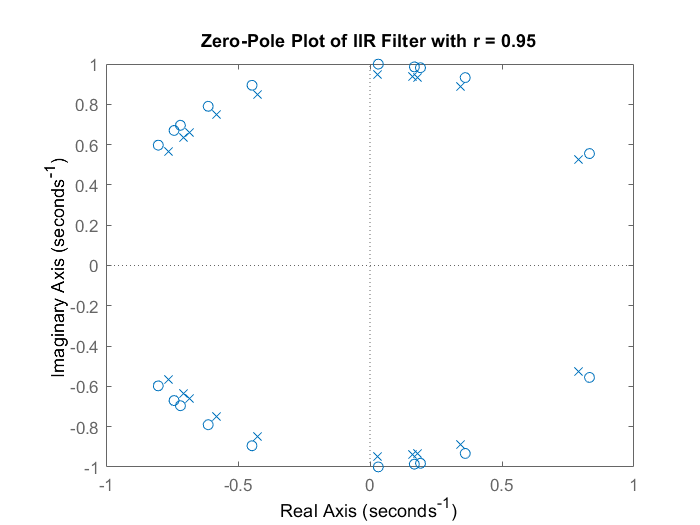

[y,Fs] = audioread('project2audio.wav');
[y_new,y_new1,y_new2] = question4(y,Fs,0.4,0.95);

Noisy audio file

soundsc(y,Fs)

Denoised audio using FIR all-zeros filter

soundsc(y_new,Fs)

Denoised audio using IIR zero-pole filter with r = 0.4

soundsc(y_new1,Fs)

Denoised audio using IIR zero-pole filter with r = 0.95

soundsc(y_new2,Fs)